# Midterm Project - Applied Math 

## Will Schenk

## 1. Decimal Conversion and Binary Representation

% Extract the decimal digits of π - 3 and convert them to binary. 

% Select the n decimal digits of pi - 3 
n = 100000; 

% Calculate N using the given formula 
N = floor(log2(10) * n);

% Calculate pi - 3 
piString = machin(n); 

% Convert pi string to array, excluding the "3." 
piArray = arrayfun(@str2num, piString(3:end)); 

% Time conversion from decimal array to binary 
tic 
binArray = decimalArrayToBinary(piArray, N); 
toc 

Elapsed time is 378.379544 seconds.



% Truncate binary array to the last zero's position 
binArray = binArray(1:find(binArray == 0, 1, 'last') - 1); 

% Save binary array to a .mat file 
save('binArray.mat', 'binArray'); 

## 2. Binary Data Analysis

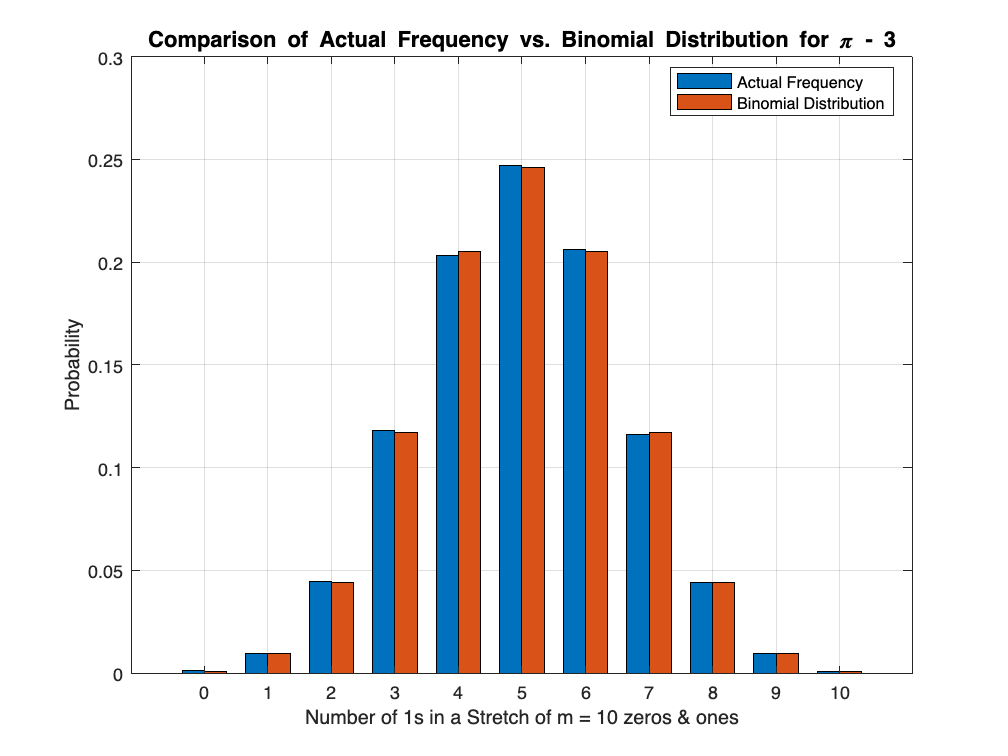

% Analyzing the frequency distribution of ones in non-overlapping stretches
% of binary data and compares it with the expected binomial distribution.

% Set stretch length 
m = 10;

% Calculate number of stretches 
numStretches = ceil(length(binArray) / m); 

% Initialize matrix to hold stretches 
binMatrix = zeros(numStretches, m); 

% Populate matrix with stretches from the binary array 
for i = 1:numStretches - 1 
    binMatrix(i, :) = binArray((i-1)*m + 1 : i*m); 
end 

% Calculate number of ones in each stretch 
rowSums = sum(binMatrix, 2); 

% Get actual frequency distribution 
frequencyActual = histcounts(rowSums, 0:m+1); 

% Calculate the expected binomial distribution 
binDistribution = zeros(1, m + 1); 
for x = 0:m 
    binDistribution(x + 1) = nchoosek(m, x) * 0.5^x * 0.5^(m - x) * numStretches; 
end 

% Calculate actual and expected probabilities 
probabilityActual = frequencyActual / numStretches; 
probabilityBinomial = binDistribution / numStretches; 

% Plot the comparison between the actual and expected probabilities 
figure; 
width = 0.35; 
xActual = (0:m) - width/2; 
xBinomial = (0:m) + width/2; 
bar(xActual, probabilityActual, width, 'DisplayName', 'Actual Frequency'); 
hold on; 
bar(xBinomial, probabilityBinomial, width, 'DisplayName', 'Binomial Distribution'); 
xticks(0:m); 
xticklabels(0:m); 
xlabel(sprintf('Number of 1s in a Stretch of m = %d zeros & ones', m)); 
ylabel('Probability'); 
title('Comparison of Actual Frequency vs. Binomial Distribution for \pi - 3', 'FontSize', 12); 
legend('Location', 'best'); 
grid on; 
hold off; 
ylim([0, 0.3]); 

## 3. Statistical Analysis

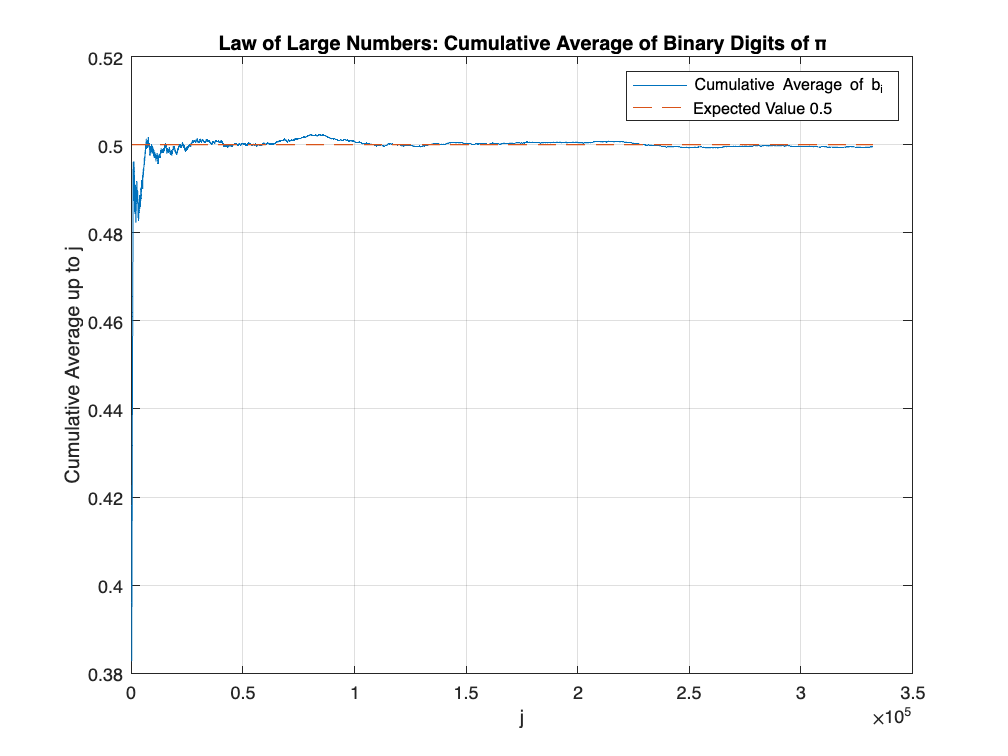

% This section evaluates the binary representation using the Law of Large Numbers 
% and the Central Limit Theorem. 

% Calculate cumulative averages for the binary data 
jValues = 100:length(binArray); 
cumulativeAverages = cumsum(binArray(1:end)) ./ (1:length(binArray)); 

% Plot the cumulative averages for values of j >= 100 
figure; 
plot(jValues, cumulativeAverages(jValues), '-', 'DisplayName', 'Cumulative Average of b_i'); 
hold on; 
plot(jValues, 0.5 * ones(size(jValues)), '--', 'DisplayName', 'Expected Value 0.5'); 
hold off; 
xlabel('j'); 
ylabel('Cumulative Average up to j'); 
title('Law of Large Numbers: Cumulative Average of Binary Digits of π'); 
legend(); 
grid on; 


% Check binary data against the Central Limit Theorem
% In this section, we divide the binary digits into non-overlapping
% stretches and check their averages against the Central Limit Theorem. 

w = 100; % Define stretch length 
K = floor(length(binArray)/w); % Compute number of non-overlapping stretches 

differences = zeros(1, K); % Initialize an array to hold differences from mean 
for i = 1:K
    segment = binArray((i-1)*w + 1 : i*w); % Extract i-th segment 
    differences(i) = mean(segment) - 0.5; % Calculate difference between mean of the segment and 0.5 
end

% Scale the differences for standard normal comparison 
scaledDifferences = differences * 2 * sqrt(w); 

% Compute the empirical PDF using custom CPDFs function 
Nb = 100; % Number of bins for the empirical PDF 
[PDF, ~, c] = CPDFs(scaledDifferences, Nb, false); 

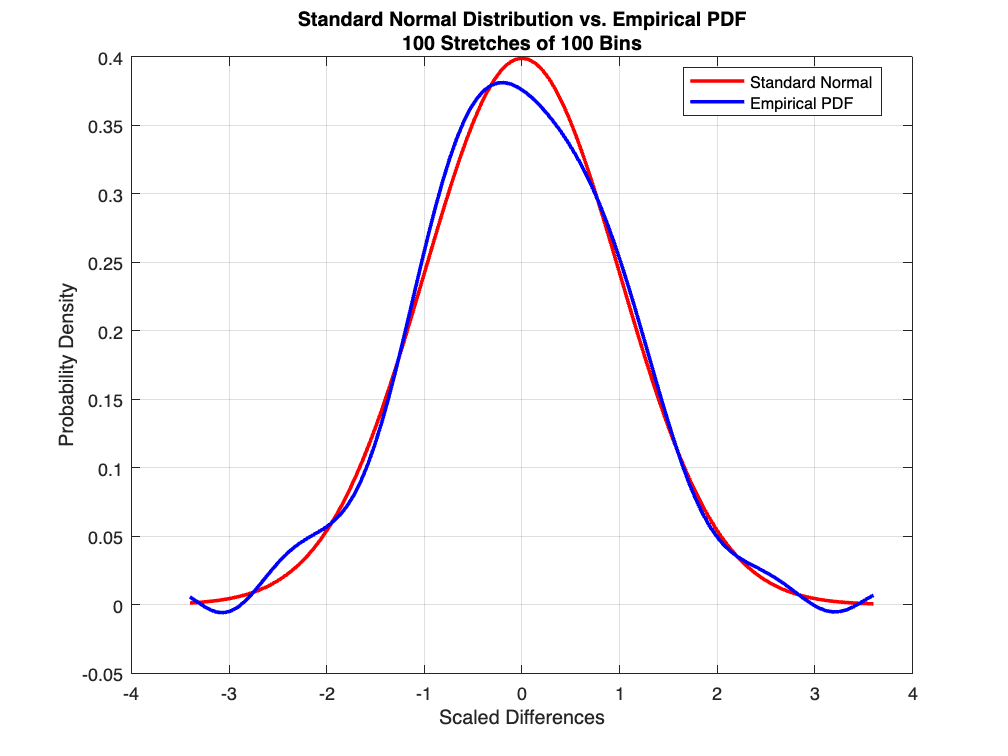

% Plot the empirical PDF alongside the standard normal distribution for
% comparison 
figure; 
x = linspace(min(scaledDifferences), max(scaledDifferences), 100); 
y = (1/(sqrt(2*pi))) * exp(-0.5 * x.^2); 
plot(x, y, 'r', 'LineWidth', 2, 'DisplayName', 'Standard Normal'); 
hold on; 
plot(c, PDF, 'b', 'LineWidth', 2, 'DisplayName', 'Empirical PDF'); 
hold off; 
xlabel('Scaled Differences'); 
ylabel('Probability Density'); 
titleStr = sprintf('Standard Normal Distribution vs. Empirical PDF\n%d Stretches of %d Bins', Nb, w); 
title(titleStr); 
grid on; 
legend('Location', 'best'); 

# Supporting Functions:

## Convert a Base 10 Array to a Base 2 Array

function binArray = decimalArrayToBinary(piArray, N) 

    % Empty Binary Array 
    binArray = zeros(1, N); 

    % Loop through each digit
    for i = 1:length(binArray) 

        % Multiply the entire array by 2. If there is a remainer at the end
        % all the way at the left side, simply add it to the first element 
        piArray = multiplyBy2(piArray); 

        % If the first element is greater than 10, this means a 1 before
        % the decimal 
        if piArray(1) >= 10 
            % Place a 1 in the binary position 
            binArray(i) = 1; 
            piArray(1) = piArray(1) - 10;  
        else 
            % Place a 0 in the binary position 
            binArray(i) = 0; 
        end 
    end 
end 

## Multiply a Binary Array by 2 

function array = multiplyBy2(array)
    carry = 0; % Remainder to carry 

    % Start at the end (rightmost element) and move to the left.
    for i = length(array):-1:1

        % Multiply the current element by 2 and add any carry
        temp = array(i) * 2 + carry; 

        % Check if the result is 10 or more
        if temp >= 10
            carry = 1; 
            temp = temp - 10;  
        else 
            carry = 0; 
        end 

        % Assign the result back to the array
        array(i) = temp; 
    end 

    % If there is a carry left at the end add it to the start 
    if carry > 0 
        array(1) = array(1) + (10 * carry); 
    end 
end 

## Calculate Decimals of Pi with Machin's Formula 

### Function Made by Yury Grabovsky 

function s = machin(m) 
    % Returns: String with pi truncated to M decimals
    % Machin's formula: pi = 16*acot(5) - 4*acot(239)
    % Author: Jonas Lundgren <splinefit@gmail.com> 2011
    
    if nargin < 1, m = 50; end 
    base = 1e15;
    n = ceil(m/15) + 1;
    
    % Machin's formula
    x = xacot(5,16,n,base) - xacot(239,4,n,base);
    
    % Canonical form
    carry = 0;
    for k = n+1:-1:1 
        xk = x(k) + carry;
        carry = floor(xk/base);
        x(k) = xk - carry*base;
    end 
    
    % Write string
    s = sprintf('%15.0f',x(2:n));
    s(isspace(s)) = '0';
    s = ['3.', s(1:m)]; 
end 

## Calculate C*ACOT(A) to N digits in base BASE 

### Function Made by Yury Grabovsky

function y = xacot(a,c,n,base)
    b = a*a;
    t = floor(base/b);
    u = base - b*t;
    m = floor(n*log(base)/log(b));
    
    % y = 0
    y = zeros(n+1,1);
    
    % y = c/(2*k+1) - y/b
    for k = m:-1:0
        nn = ceil(n-n*k/m+1);
        bb = 2*k+1;
        tt = floor(base/bb);
        uu = base - bb*tt;
        vv = c;
        v = y(1);
        qq = floor(vv/bb);
        q = floor(v/b);
        y(1) = qq - q;
        for j = 2:nn
            rr = vv - bb*qq;
            r = v - b*q;
            vv = rr*uu;
            v = y(j) + r*u;
            qq = floor(vv/bb);
            q = floor(v/b);
            y(j) = qq + rr*tt - q - r*t;
        end
    end
    % y = y/a
    r = 0;
    t = floor(base/a);
    u = base - a*t;
    for k = 1:n+1
	    v = y(k) + r*u;
	    q = floor(v/a);
	    y(k) = q + r*t;
	    r = v - a*q;
    end 
end 

## Provided Cumulative and Probability Distribution Functions 

### Function Made by Yury Grabovsky

function [Fder,F,c] = CPDFs(x,Nb,pl)
    % returns CDF and PDF of data x, using Nb bins. pl is plotting flag
    N=length(x);
    xmin=min(x); xmax=max(x);
    bin_width=(xmax-xmin)/Nb;
    bn=ceil((x-xmin)/bin_width); % decide which bin the data point x(i) goes into.
    % Note that xmin lands in bin 0, which does not exist.
    % Now count how many x(i)s are in each bin
    ind=1:Nb; % bin numbers
    [B,I]=meshgrid(bn,ind);
    s=sum(B==I,2)/N; % "==" is a logical operator, returning true or false.
    % "true" converts to number 1 and "false" to 0
    %s(1)=s(1)+1/N; % count previously excluded xmin as a member of bin #1
    f=[0;s]; % there are Nb+1 division points and s is of length Nb
    F=cumsum(f); % all partial sums (discrete antiderivative)
    f=f/bin_width; % Normalize, so that the area under the graph of f is 1
    % use polynomial approximation to F to compute its derivative
    % This will be covered in Chapter 6
    dg=20; % the degree of the approximating polynomial
    c=linspace(xmin,xmax,Nb+1);
    cpad=[xmin-(dg:-1:1)*bin_width,c,xmax+bin_width*(1:dg)]; % pad data to eliminate boundary effects
    Fpad=[zeros(dg,1);F;ones(dg,1)];
    pfit=polyfit(cpad',Fpad,dg); % polynomial approximation of data
    der_coeffs=dg:-1:1;
    pfit_der=pfit(1:end-1).*der_coeffs; % derivative of pfit
    Fder=polyval(pfit_der,c); % use the derivative of the approximating polynomial to compute values of dF/dc 
    if pl
        % plot PDF and CDF
        fs = 10; % font size
        figure %PDF
        plot(c,f,'k',c,Fder,'r','linewidth',2)
        xlabel('c')
        ylabel('f')
        title(['PDF of the data using ', num2str(Nb), ' bins'])
        set(gca,'fontsize',fs)
        axis tight
        figure %CDF
        plot(c,F,'k','linewidth',2)
        xlabel('c')
        ylabel('F')
        title(['CDF of the data using ',num2str(Nb),' bins'])
        set(gca,'fontsize',fs) 
    end 
end